# CNN para classificacao de batimentos **ectópicos** (divisao intra-paciente)

Base: MITBIH_Beats.mat

Estrutura esperada da base:

beats    -> 300 x N

labels   -> 1 x N

patientId -> 1 x N

clear; clc;

## 1) Carrega a base

basePath = 'D:\ProcessamentoDeSinais\TCC\Model\extBati\MITBIH_Beats.mat';
load(basePath);

beats = double(beats);
labels = double(labels(:).');
patientId = double(patientId(:).');

if size(beats, 2) ~= numel(labels)
    beats = beats.';
end

## 2) Divisão intra-paciente estratificada

patientList = unique(patientId);
splitFractions = [0.70, 0.15, 0.15];
idxTrain = zeros(numel(labels), 1);
idxVal   = zeros(numel(labels), 1);
idxTest  = zeros(numel(labels), 1);
trainCount = 0;
valCount = 0;
testCount = 0;

rng(42);

for i = 1:numel(patientList)
    pid = patientList(i);
    patientIndices = find(patientId == pid);

    for classValue = [0, 1]
        classIndices = patientIndices(labels(patientIndices) == classValue);
        classIndices = classIndices(randperm(numel(classIndices)));
        nClass = numel(classIndices);

        nTrain = round(splitFractions(1) * nClass);
        nVal   = round(splitFractions(2) * nClass);
        nTest  = nClass - nTrain - nVal;

        % Corrige arredondamentos sem perder ou duplicar amostras.
        while nTest < 0
            [~, largestSplit] = max([nTrain, nVal, nTest]);
            if largestSplit == 1
                nTrain = nTrain - 1;
            else
                nVal = nVal - 1;
            end
            nTest = nClass - nTrain - nVal;
        end

        trainEnd = nTrain;
        valEnd = nTrain + nVal;
        idxTrain(trainCount + (1:nTrain)) = classIndices(1:trainEnd);
        idxVal(valCount + (1:nVal)) = classIndices(trainEnd+1:valEnd);
        idxTest(testCount + (1:nTest)) = classIndices(valEnd+1:end);
        trainCount = trainCount + nTrain;
        valCount = valCount + nVal;
        testCount = testCount + nTest;
    end
end

idxTrain = sort(idxTrain(1:trainCount));
idxVal   = sort(idxVal(1:valCount));
idxTest  = sort(idxTest(1:testCount));

% Garante separacao correta
if isempty(idxTrain) || isempty(idxVal) || isempty(idxTest)
    error('A divisao intra-paciente gerou algum subconjunto vazio. Verifique a quantidade de amostras por paciente.');
end

splitEctopicCounts = [sum(labels(idxTrain) == 1), ...
    sum(labels(idxVal) == 1), sum(labels(idxTest) == 1)];
fprintf('Ectopicos por conjunto: treino=%d, validacao=%d, teste=%d\n', ...
    splitEctopicCounts(1), splitEctopicCounts(2), splitEctopicCounts(3));

Ectopicos por conjunto: treino=15374, validacao=3298, teste=3291



if any(splitEctopicCounts == 0)
    error('A divisao intra-paciente deixou algum conjunto sem ectopicos. Ajuste a base ou as proporcoes.');
end


## **3) Monta os tensores de entrada**

Xtrain = reshape(beats(:, idxTrain), [300, 1, 1, numel(idxTrain)]);
Xval   = reshape(beats(:, idxVal),   [300, 1, 1, numel(idxVal)]);
Xtest  = reshape(beats(:, idxTest),  [300, 1, 1, numel(idxTest)]);

Ytrain = categorical(labels(idxTrain), [0 1], {'Normal', 'Ectopic'});
Yval   = categorical(labels(idxVal),   [0 1], {'Normal', 'Ectopic'});
Ytest  = categorical(labels(idxTest),  [0 1], {'Normal', 'Ectopic'});
classNames = categories(Ytrain);


## 4) Arquitetura CNN 1D

Quatro convolucoes acopladas (C1-C2 e C3-C4), dois max-poolings

 (S1 e S2), dropout apos C2, C4, F1 e F2, e tres camadas densas

(a ultima foi ajustada para as duas classes desta base).

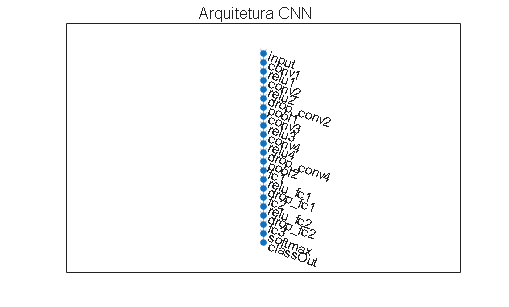

layers = [

    imageInputLayer([300 1 1], ...
        'Name', 'input', ...
        'Normalization', 'none')

    convolution2dLayer([5 1], 64, ...
        'Padding', 'same', ...
        'Name', 'conv1')
    reluLayer('Name', 'relu1')

    convolution2dLayer([5 1], 64, ...
        'Padding', 'same', ...
        'Name', 'conv2')
    reluLayer('Name', 'relu2')
    dropoutLayer(0.3, 'Name', 'drop_conv2')
    maxPooling2dLayer([2 1], ...
        'Stride', [2 1], ...
        'Name', 'pool1')

    convolution2dLayer([3 1], 128, ...
        'Padding', 'same', ...
        'Name', 'conv3')
    reluLayer('Name', 'relu3')

    convolution2dLayer([3 1], 128, ...
        'Padding', 'same', ...
        'Name', 'conv4')
    reluLayer('Name', 'relu4')
    dropoutLayer(0.3, 'Name', 'drop_conv4')
    maxPooling2dLayer([2 1], ...
        'Stride', [2 1], ...
        'Name', 'pool2')

    fullyConnectedLayer(256, 'Name', 'fc1')
    reluLayer('Name', 'relu_fc1')
    dropoutLayer(0.3, 'Name', 'drop_fc1')

    fullyConnectedLayer(128, 'Name', 'fc2')
    reluLayer('Name', 'relu_fc2')
    dropoutLayer(0.3, 'Name', 'drop_fc2')

    fullyConnectedLayer(2, 'Name', 'fc3')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classOut', ...
        'Classes', classNames)
];

deepNetworkDesigner(layers);

lgraph = layerGraph(layers);

figure;
plot(lgraph) 
sgtitle('Arquitetura CNN');

## 5) Opções de treinamento

options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-3, ...
    'MaxEpochs', 50, ...
    'MiniBatchSize', 256, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {Xval, Yval}, ...
    'ValidationFrequency', 30, ...
    'ValidationPatience', 10, ...
    'Verbose', true, ...
    'Plots', 'training-progress');


## 6) Treinamento

 Fixa a inicializacao da rede para comparacoes reproduziveis.

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:21 |       39.84% |       80.47% |       0.6987 |       0.6371 |          0.0010 |
|       1 |          30 |       00:01:15 |       91.02% |       92.51% |       0.2689 |       0.2490 |          0.0010 |
|       1 |          50 |       00:01:39 |       90.62% |              |       0.2873 |              |          0.0010 |
|       1 |          60 |       00:02:10 |       90.23% |       93.88% |       0.2197 |       0.1869 |          0.0010 |
|       

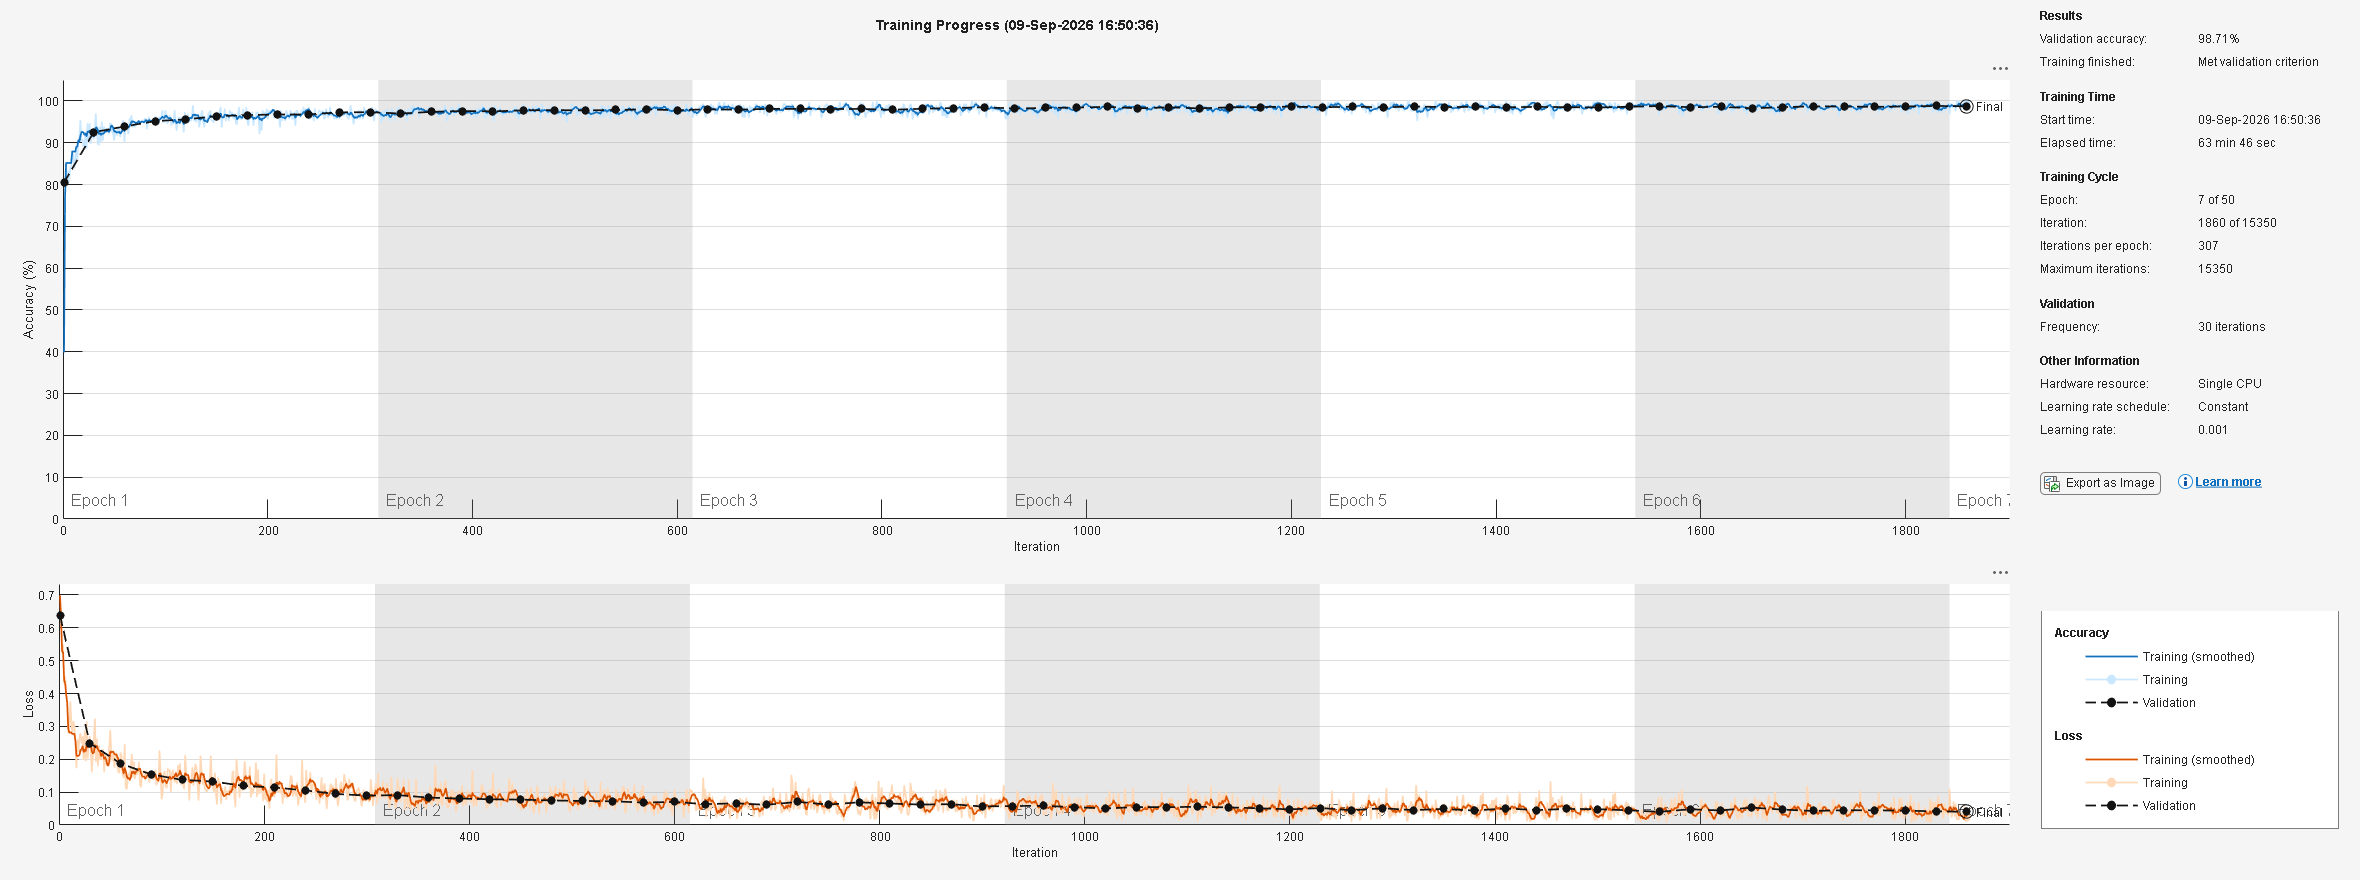

rng(42);
net = trainNetwork(Xtrain, Ytrain, layers, options);

## 7) Avaliação

% Seleciona o limiar da classe Ectopic exclusivamente na validacao,
% maximizando o F1-score. Em caso de empate, usa o valor mais proximo de 0.5.
[~, scoresVal] = classify(net, Xval);
ectopicIdx = find(strcmp(classNames, 'Ectopic'), 1);
thresholds = (0:0.01:1).';
f1Val = zeros(numel(thresholds), 1);
isEctopicVal = Yval(:) == 'Ectopic';

for i = 1:numel(thresholds)
    predEctopicVal = scoresVal(:, ectopicIdx) >= thresholds(i);
    tp = sum(predEctopicVal & isEctopicVal);
    fp = sum(predEctopicVal & ~isEctopicVal);
    fn = sum(~predEctopicVal & isEctopicVal);

    if (2 * tp + fp + fn) > 0
        f1Val(i) = (2 * tp) / (2 * tp + fp + fn);
    end
end

bestF1Val = max(f1Val);
candidateIdx = find(abs(f1Val - bestF1Val) < eps);
[~, nearestToHalf] = min(abs(thresholds(candidateIdx) - 0.5));
bestIdx = candidateIdx(nearestToHalf);
optimalThreshold = thresholds(bestIdx);

% Aplica no teste somente o limiar definido acima.
[~, scoresTest] = classify(net, Xtest);
YPred = categorical(repmat({'Normal'}, numel(Ytest), 1), classNames);
YPred(scoresTest(:, ectopicIdx) >= optimalThreshold) = 'Ectopic';

% Acuracia global
acc = mean(YPred(:) == Ytest(:));

% Classes existentes
classes = categories(Ytest);
numClasses = numel(classes);

% Matriz de confusao
cm = confusionmat(Ytest, YPred, ...
    'Order', categorical(classes));

fprintf('\n============================================\n');

fprintf('        AVALIACAO NO CONJUNTO DE TESTE\n');

        AVALIACAO NO CONJUNTO DE TESTE


fprintf('============================================\n');


fprintf('Acuracia: %.4f (%.2f%%)\n', acc, acc*100);

Acuracia: 0.9861 (98.61%)


fprintf('Limiar ótimo para Ectopic na validação: %.2f (F1 = %.4f)\n', ...
    optimalThreshold, bestF1Val);

Limiar ótimo para Ectopic na validação: 0.24 (F1 = 0.9701)



%% Calculo das metricas por classe

precision   = zeros(numClasses,1);
sensitivity = zeros(numClasses,1);
specificity = zeros(numClasses,1);
f1score     = zeros(numClasses,1);

totalSamples = sum(cm(:));

for i = 1:numClasses

    % Verdadeiros positivos
    TP = cm(i,i);

    % Falsos positivos
    FP = sum(cm(:,i)) - TP;

    % Falsos negativos
    FN = sum(cm(i,:)) - TP;

    % Verdadeiros negativos
    TN = totalSamples - TP - FP - FN;

    % Precisao / PPV
    if (TP + FP) > 0
        precision(i) = TP / (TP + FP);
    else
        precision(i) = 0;
    end

    % Sensibilidade / Recall
    if (TP + FN) > 0
        sensitivity(i) = TP / (TP + FN);
    else
        sensitivity(i) = 0;
    end

    % Especificidade
    if (TN + FP) > 0
        specificity(i) = TN / (TN + FP);
    else
        specificity(i) = 0;
    end

    % F1-score
    if (precision(i) + sensitivity(i)) > 0
        f1score(i) = 2 * ...
            (precision(i) * sensitivity(i)) / ...
            (precision(i) + sensitivity(i));
    else
        f1score(i) = 0;
    end
end

%% Tabela de resultados por classe

metricas = table( ...
    categorical(classes), ...
    precision, ...
    sensitivity, ...
    specificity, ...
    f1score, ...
    'VariableNames', { ...
    'Classe', ...
    'Precisao', ...
    'Sensibilidade', ...
    'Especificidade', ...
    'F1_Score'});

disp(' ');

disp('Metricas por classe:');

Metricas por classe:


disp(metricas);

    Classe     Precisao    Sensibilidade    Especificidade    F1_Score
    _______    ________    _____________    ______________    ________

    Normal      0.9898        0.99301          0.95776         0.9914 
    Ectopic    0.97074        0.95776          0.99301        0.96421 




%% Metricas macro

precisionMacro   = mean(precision);
sensitivityMacro = mean(sensitivity);
specificityMacro = mean(specificity);
f1Macro          = mean(f1score);

fprintf('\n--------------------------------------------\n');


--------------------------------------------


fprintf('Metricas macro:\n');

Metricas macro:


fprintf('Precisao macro:       %.4f (%.2f%%)\n', ...
    precisionMacro, precisionMacro*100);

Precisao macro:       0.9803 (98.03%)



fprintf('Sensibilidade macro:  %.4f (%.2f%%)\n', ...
    sensitivityMacro, sensitivityMacro*100);

Sensibilidade macro:  0.9754 (97.54%)



fprintf('Especificidade macro: %.4f (%.2f%%)\n', ...
    specificityMacro, specificityMacro*100);

Especificidade macro: 0.9754 (97.54%)



fprintf('F1-score macro:       %.4f (%.2f%%)\n', ...
    f1Macro, f1Macro*100);

F1-score macro:       0.9778 (97.78%)



fprintf('--------------------------------------------\n');

--------------------------------------------


## Matriz de confusão

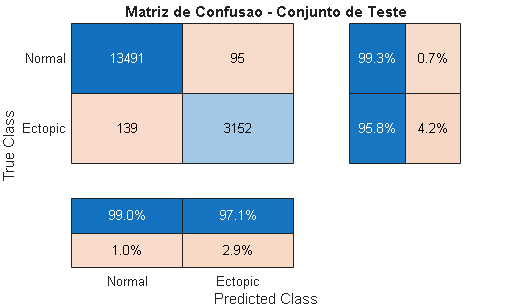


figure;

confusionchart(Ytest, YPred, ...
    'RowSummary', 'row-normalized', ...
    'ColumnSummary', 'column-normalized');

title('Matriz de Confusao - Conjunto de Teste');

### 8) Matriz de confusão normalizada

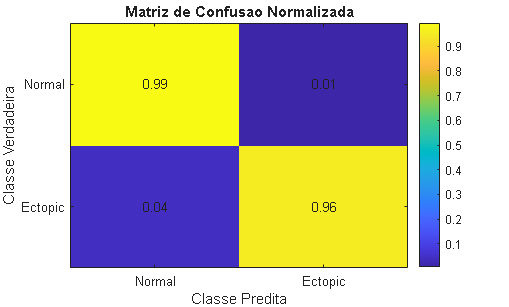


cmNormalized = cm ./ sum(cm, 2);

% Evita NaN caso alguma classe nao possua amostras
cmNormalized(isnan(cmNormalized)) = 0;

figure;

imagesc(cmNormalized);
colorbar;

title('Matriz de Confusao Normalizada');
xlabel('Classe Predita');
ylabel('Classe Verdadeira');

xticks(1:numClasses);
yticks(1:numClasses);

xticklabels(classes);
yticklabels(classes);

% Mostrar os valores dentro da matriz
for i = 1:numClasses
    for j = 1:numClasses
        text(j, i, sprintf('%.2f', cmNormalized(i,j)), ...
            'HorizontalAlignment', 'center', ...
            'VerticalAlignment', 'middle');
    end
end

## Visualização de algumas predições

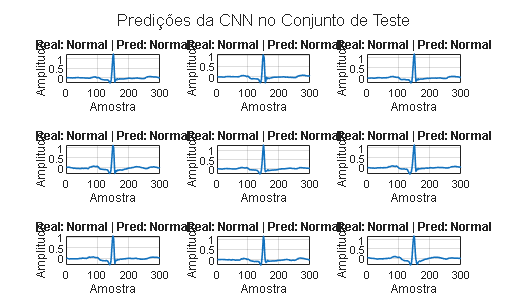

Primeira amostra do conjunto de teste:


Classe verdadeira: Normal


Classe prevista:   Normal



numSamplesPlot = min(9, numel(Ytest));

figure;

tiledlayout(3,3);

for i = 1:numSamplesPlot

    nexttile;

    % Extrai a primeira amostra
    signal = squeeze(Xtest(:,1,1,i));

    plot(signal, 'LineWidth', 1.2);
    grid on;

    title(sprintf( ...
        'Real: %s | Pred: %s', ...
        string(Ytest(i)), ...
        string(YPred(i))));

    xlabel('Amostra');
    ylabel('Amplitude');

end

sgtitle('Predições da CNN no Conjunto de Teste');